## **1. Introduction to Tutorial **

### **1.1 Objectives **

This tutorial aims to help in formant and pitch extraction. After this tutorial, one should be able to :

- Tell if an input audio segment if voiced, unvoiced or silence.

- Get the speech envelope of the signal, detect onset and ofset of speech in audio signal. 

- Extract the formants F1 and F2 as well as the pitch of the individual.

To be able to run this tutorial, Signal Processing Toolbox as well as the Audio Toolbox are required.

### **1.2 Topics Covered **

This tutorial implements several standard steps in audio signal processing. These include

- Reading in an audio signal

- Visualizing the signal, getting the envelope and speech onset and offset

- Plot spectrogram of the audio signal

- Voiced, unvoiced and silence detection

- Linear predictive coding - LPC Analysis

- Plot voice activity detection

- Formant Extraction

- Pitch Estimation

## 2. Background and key concepts

Humans have developed languages with phonemes of two major classes: vowels and consonants, each of which is distinguished by acoustic properties and spectral characteristics. When humans hear speech, they interpret the diverse audio information according to internalized learned perceptual processing, many aspects of which remain only partly understood. When machines instead process speech, they employ methods of signal *analysis*, i.e., ways to transform input acoustic data to forms more useful to assist automatic classification or to allow efficient representation.

Formants have been used to uniquely identify the different vowels in human speech and there extraction is very useful for speech prosthetics applications. 

Why do we look primarily at F1 and F2? For vowels, the tongue varies in height as the jaw is raised/lowered, which correlates inversely with the center frequency of the lowest-frequency resonance of the VT, called the first *formant* (F1). (F*i* means the center frequency of the *i* th resonance.) Lateral tongue position affects all formants, but correlates primarily with F2. To handle possible difficult environmental conditions, the frequency ranges with strongest energy are likely acoustic aspects to aim for, as they stand out amid distortions and have strong correlations to VT shape. So, speech models that emphasize spectral peaks have distinct advantages.

 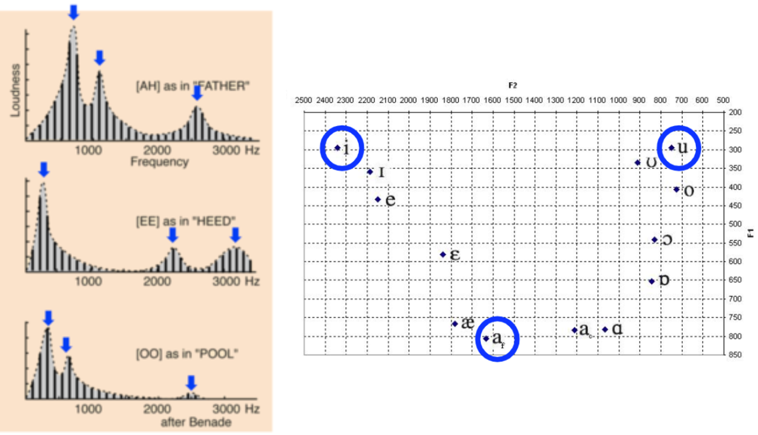

Linear predictive coding (LPC) is a widely used technique in audio signal processing, especially in speech signal processing. The original objective of LPC was to model human voice production. LPC is a source-filter model in that there is a sound source that goes through a filter. The source, e(n), models the vocal chords, while the resonant filter, h(n), models the vocal tract. LPC assumes the filter is a p-th order all-pole filter. Though not physiologically exact, it provides an extendable method for modeling resonances.

The linear prediction methods take account of resonances directly in the analysis procedure and are thus able to provide a smooth spectrum with well-defined peaks corresponding to the resonances.

The higher the order of the LPC model the more details can be extracted from the envelope of the PSD of the signal. The first two peaks represent F1 and F2.

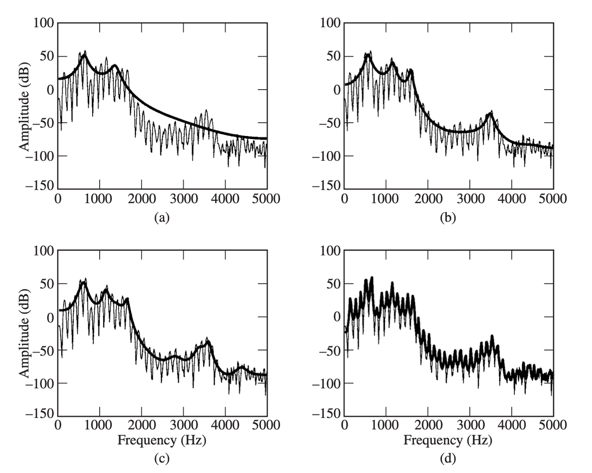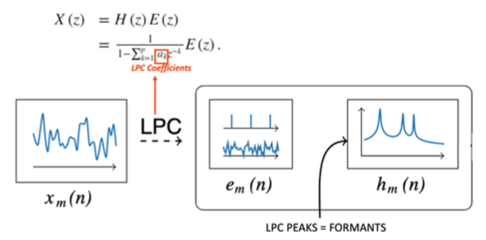

## **3. Standard steps in audio signal analysis **

First, you should import your data, audio signal, into the MATLAB workspace. If your data is a .xdf file like what we were working with, please go to the following link and download the loadxdf.m function.

[https://github.com/xdf-modules/xdf-Matlab/blob/master/load_xdf.m](https://github.com/xdf-modules/xdf-Matlab/blob/master/load_xdf.m) . If you have a normal .wav file, just import the time vetcor and audio data segment and proceed. 

Once you do that, you can use the following to get the data :

streams = loadxdf('Your_Path.xdf');

Error using loadxdf
The file "Your_Path.xdf" does not exist.


x = streams(3);
z = streams(1);
data = x{1, 1}.time_series(1,:);
time = x{1,1}.time_stamps;
fs = streams{1, 3}.segments.effective_srate;
vowelmarkers = z{1, 1}.time_series(1,:);
t_vowelmarkers = z{1, 1}.time_stamps;
y = data;
Fs = fs;
% Get time vector
t = (0:length(y)-1)*1/Fs;

#### **STEP 1 : SPEECH DETECTION**

*Zero-crossing rate* (ZCR), which is the rate at which a signal changes algebraic sign (between positive and negative values). By applying this to the energy signal we see that Unvoiced sounds have a larger ZCR than voiced sounds. 

It has been shown that a frame of 20 - 30 ms could be considered as time invariant for analysis. In order to reduce the processing time and errors in the formant extraction, we developed a way to detect the onset of speech production

The detection algorithm is based on the energy and zero-crossing rate of the input signal. In fact, during speech, the energy of the signal is high compared to periods of silence and by setting a threshold, we can detect the onset of speech production and set a classification algorithm that will detect periods of silence, unvoiced or voiced frames. 

### 3.1. Get the speech envelope :

env1 = hilbert(y);
env1 = abs(env1);

% Low pass filter
[z,p,k] = butter(8,10/(round(Fs/2)),'low');
[sos,g] = zp2sos(z,p,k);
env = filtfilt(sos,g,double(env1));
envelopeOut = env;


figure();
plot(time,data);
hold on
plot(time,envelopeOut);

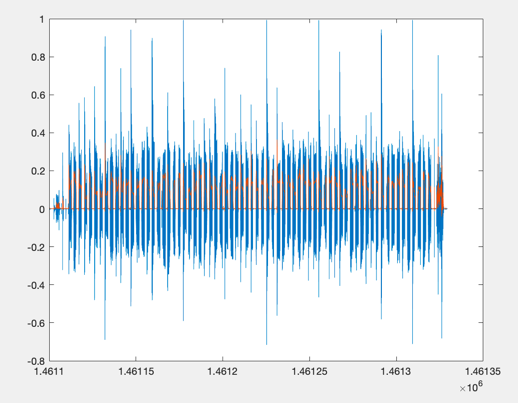

### **3.2.  Detect onset and offset of speech in the audio signal :**

This will give you the timestamps for onset and offset of speech in the variable idx where the first column is for speech onset and second column is for speech offset.

figure();
windowDuration = 0.3; % seconds
numWindowSamples = round(windowDuration*fs);
win = hamming(numWindowSamples,'periodic');

percentOverlap = 35;
overlap = round(numWindowSamples*percentOverlap/100);

mergeDuration = 0.44;
mergeDist = round(mergeDuration*fs);

detectSpeech(data',fs,"Window",win,"OverlapLength",overlap,"MergeDistance",mergeDist)
idx = detectSpeech(data',fs,"Window",win,"OverlapLength",overlap,"MergeDistance",mergeDist);
%idx holds the start and stop times of each utterance

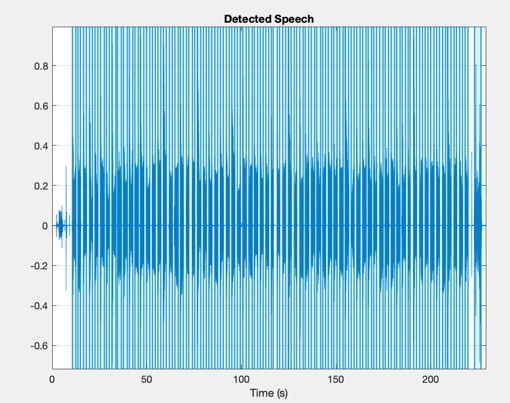

To get a better sense of the windowing methods used in the later steps, we should first see the different lengths of the speech parts and silence parts of the input audio signal.

speechlength = []; splen = 1;
silencelength = []; silen = 1;

for i = 1:1:size(idx,1)-1
    splen = time(1,idx(i,2)) - time(1,idx(i,1));
    silen = time(1,idx(i+1,1)) - time(1,idx(i,2));
    speechlength = [speechlength splen];
    silencelength = [silencelength silen];
end

figure();
histogram(speechlength)
title("Histogram for Length of Speech Chuncks");
xlabel("Utterance length (s)")
ylabel("Number of chunks");

figure();
histogram(silencelength)
title("Histogram for Length of Silence Chuncks");
xlabel("Silence length (s)")
ylabel("Number of chunks");

### **3.3. Spectrograms :**

Another way to look at the audio signal is in the frequency domain. One way to do that is by computing and plotting the spectrogram of the audio signal.

Tw = [0.1, 0.35];
Ts = Tw(1)/2;

% Window size in samples
windowSize = [Tw(1)*Fs, Tw(2)*Fs];
windowOverlap = ceil(Ts * Fs);
nfft = [2^nextpow2(windowSize(1)), 2^nextpow2(windowSize(2))];

% Generate hamming window
wideWindow = hamming(windowSize(1));
narrowWindow = hamming(windowSize(2));

Plot the spectrograms

figure('name', 'Spectrogram for wide window')
spectrogram(y, wideWindow, windowOverlap, nfft(1), Fs, 'yaxis')
title(['Using ', num2str(nfft(1)), ' DFT points'])

figure('name', 'Spectrogram for narrow window')
spectrogram(y, narrowWindow, windowOverlap, nfft(2), Fs, 'yaxis')
title(['Using ', num2str(nfft(2)), ' DFT points'])

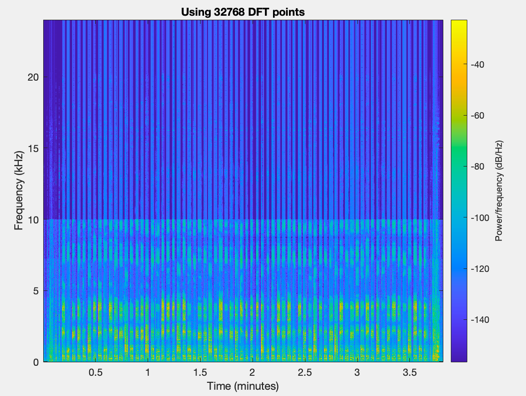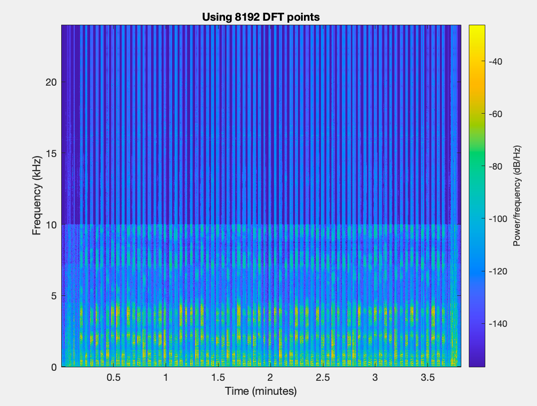

#### **STEP 2 : VOICED, UNVOICED AND SILENT FRAMES DETECTION**

After using a hamming window on the audio signal,  each frame is going to be labeled as either voiced, unvoiced or silent. the goal of this step is to lower the random states detected in the silent frames.

The Formant extraction algorithm will then only be run on the frames labeled as voiced. Here, wide window parameter are being used.

window  = ceil(0.010*4 * Fs);
overlap = ceil(0.005 * Fs);

% Buffer speech signal into matrix of data frames
dataframes = buffer(y, window, overlap, 'nodelay')';
num_df = size(dataframes, 1);

% Initialize vectors
E = zeros(1,num_df);
ZCR = zeros(1,num_df);
decision = zeros(1,num_df);
pitch = zeros(1,num_df);
F1 = [];
F2 = [];
tt = [];
voiced = 0;


The variables F1 and F2 will hold the formant values for each input frame.

for k = 100:num_df-40
    % Extract one frame
    x = double(dataframes(k,:));
    
    % Compute its energy
    E(k) = sum(x.^2);
    
    % Compute its zero-crossing rate
    ZCR(k) = sum(abs(diff(x>0)))/length(x);
    
    % Check if the frame is voice, no voice or, silence
    decision(k) = Detect(E(k), ZCR(k));
    
    % Compute pitch and extract formants for voiced frames
    if decision(k) == 2 % i.e., voice
        voiced = voiced + 1;
        pitch(k) = Pitch(x, Fs);
        [f1,f2,tt1] = formants(x,Fs,k,50);
        F1 = [F1 f1];
        F2 = [F2 f2];
    end
end

voicedFrame = zeros(window, 1);
unvoicedFrame = zeros(window, 1);


% Isolate a voiced frame
t_voiced = (0:length(voicedFrame)-1)*1/Fs;
for k = 1:num_df
    if decision(k) == 2
        voicedFrame = dataframes(k, :);
        break;
    end
end

% Isolate an unvoiced frame
t_unvoiced = (0:length(unvoicedFrame)-1)*1/Fs;
for k = 1:num_df
    if decision(k) == 1
        unvoicedFrame = dataframes(k,:);
        break;
    end
end

voiced = zeros(1, numel(decision));
unvoiced = zeros(1, numel(decision));
silence =  zeros(1, numel(decision));

for k = 1:numel(decision)
    if decision(k) == 0         % silence
        voiced(k) = NaN;
        unvoiced(k) = NaN;
    elseif decision(k) == 1     % unvoiced
        unvoiced(k) = 1;
        voiced(k) = NaN;
        silence(k) = NaN;
    else                        % voiced
        voiced(k) = 2;
        unvoiced(k) = NaN;
        silence(k) = NaN;
        
    end
end

The two functions Pitch and formants will be explained later in this tutorial.

Plot energy and zero-crossing rate of the signal using the following :

figure('name', 'Energy and Zero-Crossing Rate')
subplot(3,1,1)
plot(t, y), grid on
title('Input Signal'), xlabel('Time (s)')

subplot(3,1,2)
plot(E, '-'), grid on
title('Energy'), xlabel('Frames')

subplot(3,1,3)
plot(ZCR, '-'), grid on
title('Zero-Crossing Rate'), xlabel('Frames')

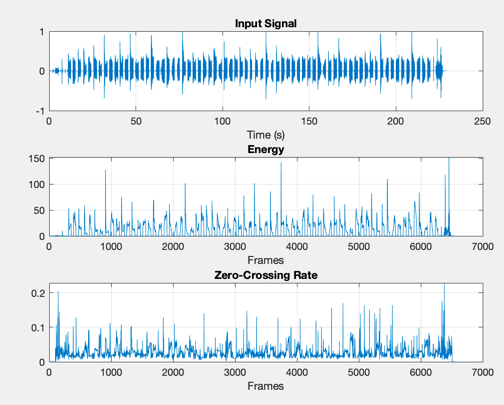

You can also plot this for individual frames. 

Plot the voice activation detection.

figure('name', 'Voice Activity Detection')
subplot(2,1,1), plot(t,y), grid on
title('Input Signal'), xlabel('Time (s)')

subplot(2,1,2)
plot(1:num_df, silence, 'b', ...
     1:num_df, unvoiced, 'y+', ...
     1:num_df, voiced, 'r*')
grid on, ylim([-1 3])
title('Voiced-Unvoiced-Silence Detection'), xlabel('Frames'), ylabel('Classification')
legend('silence', 'unvoiced', 'voiced')

## 4. Frame Detetction Function

To asses whether a frame is voiced, unvoiced or silent based on the ZCR and energy of the imput signal, use the following function :

function decision = Detect(energy, zcr)
% Detect() classifies the frame to three main classes: 
%           VOICED
%           UNVOICED, and 
%           SILENCE
% The tresholds are calculated by observing the zcr and energy plot.
%
% ARGUMENTS:
%           energy - energy of the frame
%           zcr - zero-crossing rate of the frame
% RETURNS:
%           decision - 0 for silence, 1 for unvoiced, 2 for voiced

low_energy = 4*10^(-3);
high_energy = 1*10^(-2); 

low_zcr = 0.03;
high_zcr = 0.9;
n = length(energy);
decision = zeros(1,n);

for k = 1:n
    if energy(k) < low_energy
        if zcr(k) < low_zcr
            decision(k) = 0;
        elseif zcr(k) < high_zcr
            decision(k) = 0;
        end
    elseif energy(k) < high_energy
        if zcr(k) < low_zcr
            decision(k) = 1;
        elseif zcr(k) < high_zcr
            decision(k) = 2;
        else
            decision(k) = 1;
        end
    else
        decision(k) = 2;
    end
end
end

## 5. Formant Extraction Function

This function is used to extract the formants for the given input frame of audio. It uses the LPC method where LPC based features should be applied on the time domain signal.

 LPC widens the signal, models the signal as 1/signal. The formants will be the zeros of the lpc function. You can plot the formants using different lpc coefficients and see the difference in precision

and accuracy. The best results where obtained for LPC model of order between 15 and  8.

function [F11,F22,tt] = formants(x,fs,k,order)

% ARGUMENTS:
%           x - signal frame
%           fs - sampling frequency
%           k - decision
%           order - LPC model order
% RETURNS:
%           F11 - first formant value
%           F22 - Second formant value
%           tt - time vector

% get Linear prediction filter

    a = lpc(x,order);

% find frequencies by root-solving

    r = roots(a); % find roots of polynomial a
    r = r(imag(r)>0.01); % only look for roots >0Hz up to fs/2
    ffreq = sort(atan2(imag(r),real(r))*fs/(2*pi));  
    F11 = ffreq(1);
    tt = k*fs;
    F22 = ffreq(2);
end

This function uses the LPC function descrobed below :

function [Y, fs] = DFT(y, f)
% DFT() computes and plot sdcrete fourier transform of a given signal y
%
% ARGUMENTS:
%           x - signal
%           f - sampling frequency
% RETURNS:
%           Y - DFT of the input signal y
%           fs - sampling frequency

L = length(y);
nfft = 2^nextpow2(L); 
Y = fft(y, nfft)/L;
fs = f/2*linspace(0, 1, nfft/2+1);

% Plot single-sided amplitude spectrum
plot(fs, 2*abs(Y(1:nfft/2+1))) 
title('Discrete Fourier Transform')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
end

function [coef, error, allpole] = LPC(x, order)
% LPC() calculates the LPC coefficients and performs signal estimation
%
% ARGUMENTS:
%           x - signal
%           order - pth order of the filter
% RETURNS:
%           coef - LPC coefficients
%           error - error estimate
%           allpole - all-pole transfer function

[coef, g] = lpc(x, order);
coef = 0 - coef(2:end);
est_x = filter(coef, 1, x);
error = x - est_x;
allpole = filter(sqrt(g), [1 coef], est_x);

end


## 6. Pitch extraction function 

In order to extract the pitch of the signal, use the following function :

function pitch = Pitch(x, f)
% Pitch() calculates the the pitch for a framed signal
%
% ARGUMENTS:
%           x - frame signal
%           f - sampling frequency
% RETURNS:
%           pitch - fundamental frequency

[n,m] = size(x);
pitch = zeros(n,1);
for k = 1:n
    c = ifft(log(abs(fft(x(k, :), m)) + eps));
    [~, idx] = max(abs(c));
    pitch(k) = f/idx;
end
end